%
% Chen YANRU and SR Kharche.
% Feb 2020.
% Part of PM3 platforms.
% Tag: Barry Janssen micro-vasculature study.
%
% To work out connectivity in nodes.
%
% Input: (x,y) coordinates obtained by manual segmentation of one image using ImageJ.
% Input: one image (tiff).
%
% Output: Manually generated segments.
% the nodes are organised as a list of (x,y). Give them node number 0, 1, 2, 3, ...
% Using this script, work out segments: parent node number, daughter node number.
% for arterioles, there will be 1 parent and 0, 1, or 2 daughters.
% for venules, there will be 1 or 2 parents for each daughter.
%
clear all
clear all
close all
close all
%
%
% load the tiff. Either fov0_1 or fov0_5. Both vasculatures are the same, less red blood cells in fov01, more in fov05.
% also, less number of blood vessels with RBCs in fov01.
t = Tiff('Image_000500.tif','r');

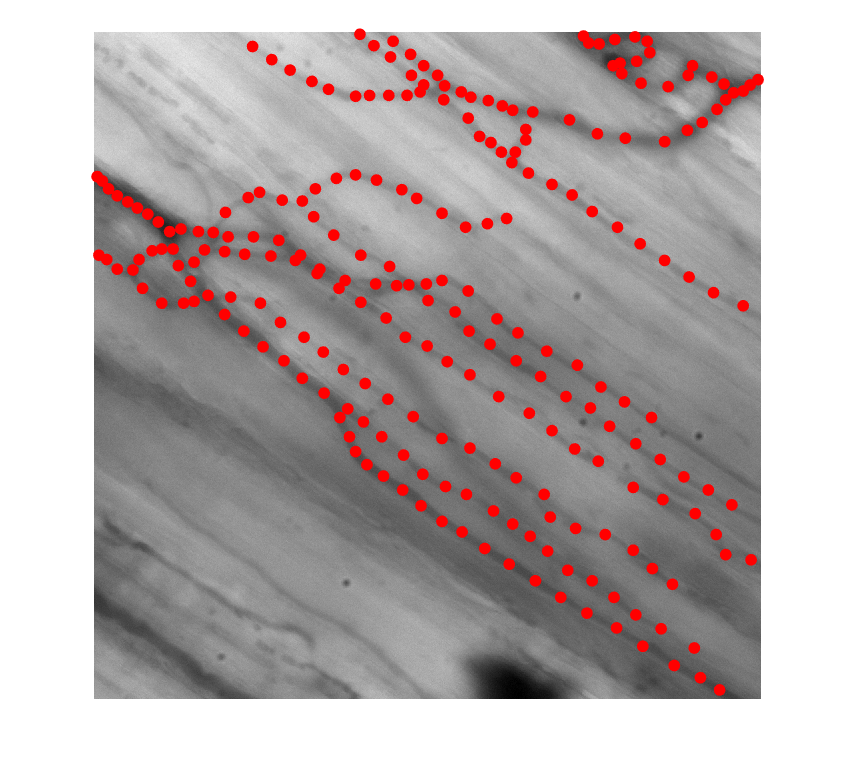

ImageData = read(t);
%
% load the (x,y) file.
cy_xy = load('Image_000500--x,y.txt');
%
% superimpose both.
%
imshow(ImageData);
hold on;
scatter(cy_xy(:,1), cy_xy(:,2),50, 'o', 'filled','red','LineWidth',0.1);